Homework -- Predictor-Corrector Methods

Kathryn Atherton

ABE 30100

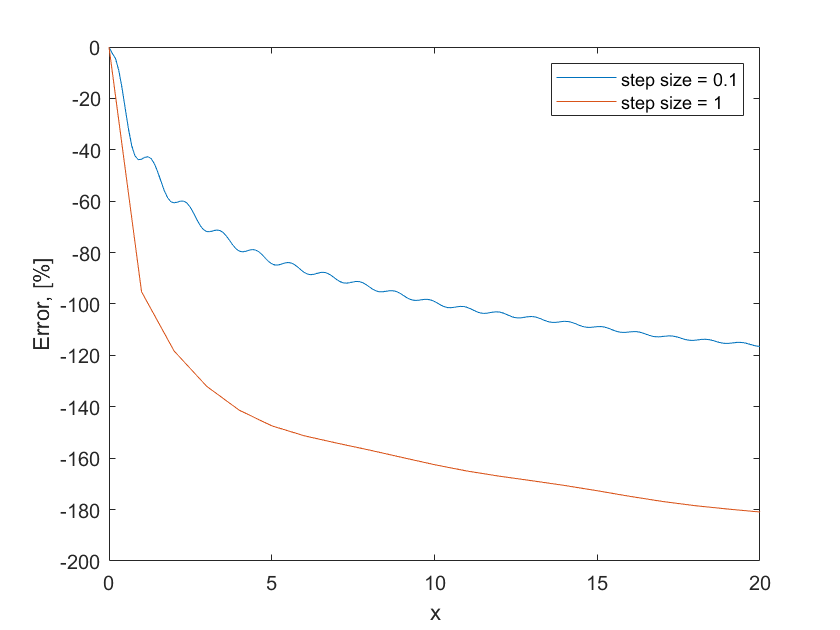

syms x;
deriv = (5.9 - cos(5.9 - x)) / (x + 0.1) - (sin(5.9 * x) + 0.3) / (x + 0.1) ^ 2;
xi = 0;
xf = 20;
yi = 27;


[x_solve_01, y_solve_01] = euler_deriv(deriv, xi, xf, 0.1, yi);
[x_solve_1, y_solve_1] = euler_deriv(deriv, xi, xf, 1, yi);

y_solve_01 = y_solve_01.';
y_solve_1 = y_solve_1.';

f = (0.3 + sin(5.9 * x)) / (x + 0.1) + 24;
y_actual_01 = subs(f, x, x_solve_01);
y_actual_1 = subs(f, x, x_solve_1);

error_01 = (y_actual_01 - y_solve_01) ./ y_actual_01 .* 100;
error_1 = (y_actual_1 - y_solve_1) ./ y_actual_1 .* 100;

plot(x_solve_01, error_01)
hold on
plot(x_solve_1, error_1);
hold off
xlim([0,20]);
xlabel('x');
ylabel('Error, [%]');
legend('step size = 0.1', 'step size = 1');

The smaller step size has a smaller error from the analytical solution.

The solutions for step size = 1 progressively get less and less accurate with a negative error, nearing 200%. 

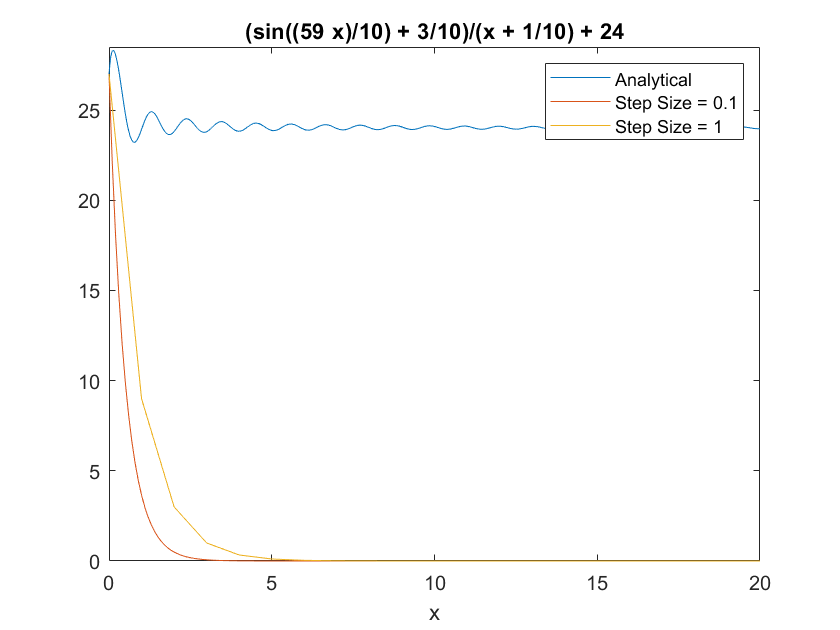

ezplot(f,[0,20])
ylim([0,28.5]);
hold on;

y0 = 27;                  % Initial Condition
h=0.1;                   % Time step
t = 0:h:20;               % t goes from 0 to 2 seconds.
yexact = double(subs(f,x,t));     % Exact solution (in general we won't know this
ystar = zeros(size(t));  % Preallocate array (good coding practice)

ystar(1) = y0;           % Initial condition gives solution at t=0.
for i=1:(length(t)-1)
  
  k1 = -2*ystar(i);  % Approx for y gives approx for deriv
  y1 = ystar(i)+k1*h/2;      % Intermediate value (using k1)
  
  k2 = -2*y1;        % Approx deriv at intermediate value.
  y2 = ystar(i)+k2*h/2;      % Intermediate value (using k2)
  
  k3 = -2*y2;        % Another approx deriv at intermediate value.
  y3 = ystar(i)+k3*h;        % Endpoint value (using k3)
  
  k4 = -2*y3;        % Approx deriv at endpoint value.
  
  ystar(i+1) = ystar(i) + (k1+2*k2+2*k3+k4)*h/6; % Approx soln
end
plot(t,ystar);
hold on

y0 = 27;                  % Initial Condition
h=1;                   % Time step
t = 0:h:20;               % t goes from 0 to 2 seconds.
yexact = double(subs(f,x,t));     % Exact solution (in general we won't know this
ystar = zeros(size(t));  % Preallocate array (good coding practice)

ystar(1) = y0;           % Initial condition gives solution at t=0.
for i=1:(length(t)-1)
  
  k1 = -2*ystar(i);  % Approx for y gives approx for deriv
  y1 = ystar(i)+k1*h/2;      % Intermediate value (using k1)
  
  k2 = -2*y1;        % Approx deriv at intermediate value.
  y2 = ystar(i)+k2*h/2;      % Intermediate value (using k2)
  
  k3 = -2*y2;        % Another approx deriv at intermediate value.
  y3 = ystar(i)+k3*h;        % Endpoint value (using k3)
  
  k4 = -2*y3;        % Approx deriv at endpoint value.
  
  ystar(i+1) = ystar(i) + (k1+2*k2+2*k3+k4)*h/6; % Approx soln
end
plot(t,ystar);
hold off
legend('Analytical', 'Step Size = 0.1', 'Step Size = 1')

The numerical solutions start relatively acccurately, but quickly both solutions go to zero and never recover. They behave this way because of the initial sharp negative slope; had there been an even smaller step size, this sharp negative slope would not have had such a destructive effect on the solution. For both the Euler and the RK solutions, the smaller the step size, the more accurate the method; this does, however, make the program slower, so a balance must be found between accuracy and speed. 

function [x_solve, y] = euler_deriv(deriv, xi, xf, delx, yi)
if (xi > xf) && (delx > 0)
    error('Error: Euler method will never converge on final x value. Check final x and delta x values.');
elseif (xi < xf) && (delx < 0)
    error('Error: Euler method will never converge on final x value. Check final x and delta x values.');
elseif delx == 0
    error('Error: delx = 0. Please enter a nonzero delta x.');
else
    y = zeros(length(xi:delx:xf), 1); 
    i = 1;
    x_solve(i) = xi; 
    y(i) = yi;    
    while x_solve(i) <= xf
        x = x_solve(i);
        slope = double(subs(deriv));
        y_new = y(i) + slope * delx;
        y(i + 1) = double(y_new);
        x_solve(i + 1) = x_solve(i) + delx; 
        i = i + 1;
    end
end
end